# Sinusoidal Signal Analysis

- *Electric Circuits Virtual Labs *

- *Author: Zekeriya Aliyazicioglu, Dennis Dahlquist*

## Introduction

We are interested in electrical circuit which has a sinusoidal voltage or current signal sources. Sinusoidal signal sources and their effects on circuit behavior form are important area of study for several reasons.  

- A sinusoidal signal is easy to generate and has been used in homes, factories, laboratories.  

- It is also the main form of signal in the communications and electric power industries. 

- Any practical periodic signal can be represented by a sum of sinusoidal signals using Fourier analysis. 

- A sinusoidal signal is easy to handle mathematically.

If the sources of a circuit are sinusoids, the circuit can be called an Alternating Current (AC) circuit. A sinusoidal signal can be described as the frequency, the magnitude, and the phase.  The response of the AC circuit has the same frequency as the input but the magnitude and phase angle can change depends on the frequency. 

## Learning Objectives

Be able to 

- Explain the Sinusoidal signal in the phasor form

- Explain  the concepts of impedance and admittance in the phasor concepts.

- Transform a circuit with a AC source into the phasor form

- Apply KCL and KVL in the phasor transformed circuit.

- Analyze AC circuits in the phasor transformed to determine their steady-state response

## Sinusoidal Signal  

The phasor in a polar coordinate system is the magnitude and phase of  a sinusoidal signal. The phasor form  is a useful tool in analyzing  circuits with sinusoidal sourses.  

A cosine signal is given as 

        
$$v(t)=V_m cos(\omega t+\theta)$$


and it has three parameters: the amplitude $V_m$, the frequency $\omega $ in radians , and the phase $\theta$. t is the time which is independent variable. $\omega $ can be represented as

            
$$\omega =2\pi f$$


where $f$ is the frequency in $Hz$. The signal period can be calculated as $T=\frac{1}{f}$

#### Example 1. Cosine signal

    Consider the following signal.  

        $v(t)=6cos \Big ( 2\pi 100 t-\frac{\pi}{4} \Big)$ or $v(t)=6cos  ( 2\pi 100 t-45^^\circ)$

    Plot the signal $v(t)$in 4 period. Find signal parameters the amplitude $V_m$, the frequency $\omega $ in radians , and the phase $\theta$

**Solution:**

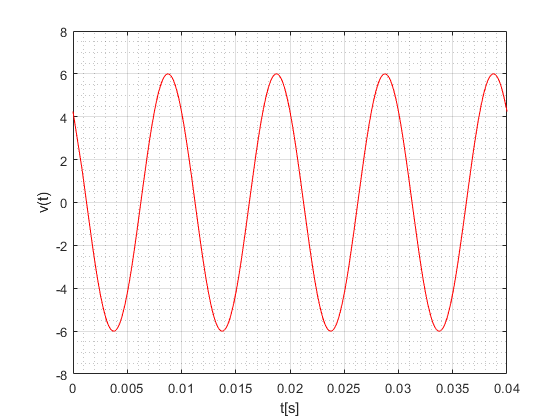

syms v(t)
f = 100; Vm = 6; theta = -pi/4;
v(t) = Vm*cos(2*pi*f*t-theta);
T = 1/f;
figure ()
fplot(v(t),[0 4*T],'r')
axis([0 4*T -Vm-2 Vm+2])
grid on; grid minor
xlabel('t[s]'); ylabel('v(t)')

The signal parameters can be found as

        $V_m=6 $,     $\omega=2 \pi 100 [rad/s]$,      $\theta=- \frac{\pi}{4}$.

#### Exercise 1. Cosine signal

    Consider the following signal.  

                
$$v(t)=12cos \Big ( 2\pi 120 t+\frac{\pi}{3} \Big)$$
 

    Plot the signal $v(t)$in 4 period. Find signal parameters the amplitude $V_m$, the frequency $\omega $ in radians , and the phase $\theta$

**Solution steps:**

% syms v(t)
% f = ? ; Vm = ? ; theta = ?;
% v(t) = ?;
% T = 1/f;
% figure ()
% fplot(v(t),[0 4*T],'r')
% axis([0 4*T -Vm_2 -Vm+2])
% grid on;  grid minor;
% xlabel('t[s]');  ylabel('v(t)')

    Find the signal parameters

#### Example 2. Cosine Signal (AC signal)

    Consider the following signal.

             
$$v(t)=5 sin \Big ( 2\pi 100 t-\frac{\pi}{6} \Big)$$


    Find the signali$v(t)$in cosine forma and plot it in 4 period. 

    Find signal parameter the amplitude $V_m$, the frequency $\omega $ in radians , and the phase $\theta$

**Solution:**

    Let's conver signal to cosine form 

            
$$v(t)=5 sin \Big ( 2\pi 100 t-\frac{\pi}{6} \Big)= 2cos \Big( 2\pi 100 t-\frac{\pi}{2}-\frac{\pi}{6} \Big)= 2cos \Big( 2\pi 100 t-\frac{2\pi}{3} \Big)$$
 

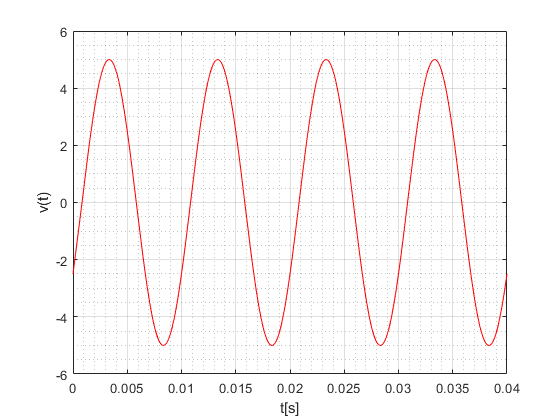

syms v(t)
f = 100;
omega = 2*pi*f;
v(t) = 5*cos(2*pi*f*t-2*pi/3);
T = 1/f;
figure ()
fplot(v(t),[0 4*T],'r')
axis([0 4*T -6 6])
grid on; grid minor;
xlabel('t[s]'); ylabel('v(t)');

    Signal parameters

            $V_m=5 $, $\omega=2 \pi 100 [rad/s]$,   $\theta=- \frac{2\pi}{3}$.

#### Exercise 2. Cosine signal

    Consider the following signal.

             
$$v(t)=-5 sin \Big ( 2\pi 100 t+\frac{\pi}{6} \Big)$$
 

    Find the signali$v(t)$in cosine forma and plot it in 4 period. 

    Find signal parameter the amplitude $V_m$, the frequency $\omega $ in radians , and the phase $\theta$

**Solution steps:**

    Conver signal to cosine form 

    Plot it

% syms v(t)
% f = ?;
% omega = ?;
% v(t) = ?;
% T = 1/f;
% figure ()
% fplot(v(t),[0 4*T],'r')
% axis([0 4*T -6 6])
% grid on;  grid minor;
% xlabel('t[s]'); ylabel('v(t)');

    Define the signal parameter

### Cosine signal in Phasor Form

The phasor in a polar coordinate system represents the magnitude and phase of the signal. 

            
$$V=V_m \angle \theta$$


#### Example 3. Phasor Form

    Find the phasor form of the folloing signals

   a. $v(t)=5 sin \Big ( 2\pi 100 t+\frac{\pi}{6} \Big)$

    b. $v(t)=-5 sin \Big ( 2\pi 100 t+\frac{\pi}{6} \Big)$     

**Solutions:**

    a. $v(t)=5 sin \Big ( 2\pi 100 t+\frac{\pi}{6} \Big)==5cos \Big ( 2\pi 100 t+\frac{\pi}{6} -\frac{\pi}{2}\Big)= 5cos \Big ( 2\pi 100 t-\frac{\pi}{3} \Big)$,   $V=5 \angle \frac{-\pi}{3}=5 \angle -60^\circ$

    b. $v(t)=-5 sin \Big ( 2\pi 100 t+\frac{\pi}{6} \Big)=5 cos \Big ( 2\pi 100 t+\frac{\pi}{6} -\frac{\pi}{2}+\pi\Big)= 5 cos \Big ( 2\pi 100 t+\frac{2\pi}{3} \Big)$, $V=5 \angle \frac{2\pi}{3}=5 \angle 120^\circ$

#### Exercise 3. Phasor Form

    Find the phasor form of the folloing signals

     
$$v(t)=-5 sin \Big ( 2\pi 100 t-\frac{\pi}{6} \Big)$$


### Conversion Between Cartesian  Coordinate System and  Polar Coordinate System                   

#### Polar to Cartesian

A phasor given by $V=V_m\angle\theta$ represents a complex number $V=V_m e^{j\theta}$. According to Euler’s rule, we have

        
$$V=V_m e^{j\theta}=V_mcos(\theta)+jV_msin(\theta)$$


The MATLAB function `[Va,Vb] = pol2cart(`$\theta$`,Vm)` provides direct conversion from polar coordinates to Cartesian coordinates. The phase angle $\theta$ is in radians.

#### Cartesian to Polar

If we have complex voltage as $V=V_a+jV_b$. Then, a complex number can be  represented in Cartesian coordinate system and  written as

        
$$V=V_a+jV_b=\sqrt{V_a^2 +V_b^2 }  \angle tan^{-1}\Big (\frac{V_b}{V_a} \Big )=V_m e^{j\theta}$$


The MATLAB function `[`$\theta$`,Vm] = cart2pol(Va,Vb)` provides direct conversion from Cartesian coordinates to polar coordinates. `abs(Va+Vbj)` provides magnitude and `angle(Va+Vbj)` provides the phase.

#### **Example 4. Conversion **polar to cartesian and cartesian  to polar

   a. Convert the following number in polar to cartesian coordinates.

                1. $V=60 \angle-120^\circ$     2. $V=24 \angle135^\circ$

   b. Convert the following numbers in cartesian coordinates to polar coordinates.

                1.  $V=3+j4$     2. $V=-5+j4$

**Solution:**

% Polar to Cartesian 
[Va, Vb] = pol2cart (-120*pi/180,60)
V = complex(Va,Vb)

V = -30.0000 - 51.9615i


[Va, Vb] = pol2cart (135*pi/180, 24)

Va = -16.9706

Vb = 16.9706

V=complex(Va,Vb)

V = -16.9706 + 16.9706i


%Cartesian to Polar
[theta, V]=cart2pol(3,4)

theta = 0.9273

V = 5

[theta, V]=cart2pol(-5,4)

theta = 2.4669

V = 6.4031

#### **Exercise 4. Conversion **polar to cartesian and cartesian  to polar

    a.  Convert the following number in polar to cartesian coordinates.

                1.  $V=20 \angle-45^\circ$     2. $V=12 \angle75^\circ$

    b. Convert the following numbers in cartesian coordinates to polar coordinates.

                1.  $V=-5-j8$     2. $V=5-j6$

**Solution steps:**

% % Polar to Cartesian 
% [Va, Vb] = ? ;
% V = complex(Va,Vb)
% [Va, Vb] = ?;
% V=complex(Va,Vb)
% 
% %Cartesian to Polar
% [theta, V] = ?
% [theta, V] = ?

### Resistor

if v(t) be the voltage across the resistor and i(t) be the current through the resistor, Ohms' law is  given in time domain

        
$$v(t)=Ri(t)$$


The voltage $v(t)=V_m cos(\omega t+\theta)$ is given in the phasor form as  $V=V_m e^{j\theta}$

Then the current $i(t)=I_m cos(\omega t+\theta)$ will be in phasor form as   $I=I_m e^{j\theta}$

        
$$I=\frac{V}{R}=\frac{V_m e^{j\theta }}{R}=\frac{V_m}{R}e^{j\theta }=I_me^{j \theta}$$


### Capacitor

The current i(t) through the capacitor is related to the voltage v(t) across the capacitor

        
$$i(t)=C \frac{dv(t)}{dt}$$


The phasor of the current I is given

        
$$I=j\omega CV=j\omega C V_me^{j\theta} =\omega C V_me^{j( \theta+\frac{\pi}{2})}$$


The impedance of the capacitor is given 

        
$$X_C=\frac{V}{I}=\frac{1}{j\omega C}=\frac{-j}{\omega C}= \frac{1}{\omega C}e^{-j\frac {\pi}{2}}$$


### Inductor

The current i(t) through the inductor is related to the voltage v(t) across the inductor as

        
$$i(t)=\frac{1}{L} \int_{-\infty}^t v(\tau)t\tau$$


The phasor of the current I is given

        
$$I=\frac{V}{j\omega L}=\frac{V_m e^{j\theta}}{j\omega L}=\frac{V_m e^{j(\theta-\frac{\pi}{2})}}{\omega L}$$


The impedance of the inductor is given 

        
$$X_L=\frac{V}{I}=j \omega L=\omega Le^{j\frac {\pi}{2}}$$


### Phasor-Transformed Circuit

If the voltage sources and current sources are sinusoids in the circuit, these sources can be transformed into voltage phasors and current phasors forms. The circuit elements can be transformed into the impedances. Consisting of voltage phasors, current phasors, and impedances circuit are called phasor-transformed circuits.  Circuit laws and theorems for circuits can be applied to phasor-transformed circuits, including

- Kirchhoff’s current law (KCL),

- Kirchhoff’s voltage law (KVL),

- The voltage divider rule, and the current divider rule,

- Nodal analysis, mesh analysis,

- Source transformation,

- Thévenin’stheorem, and Norton’s theorem

#### Example 5. Phasor-transformed circuit

Find the voltage $v_0(t)$ and current $i(t)$ in the circuit below for $v_s(t)=12cos(2\pi100t+60^\circ) $

            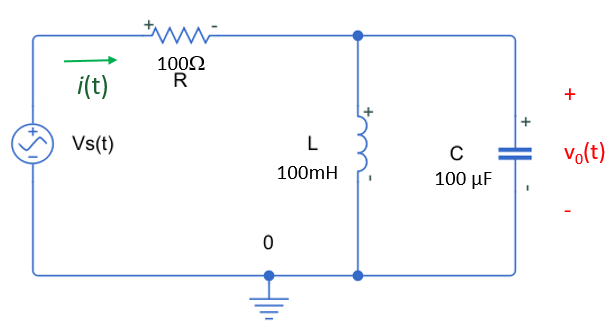

Given values in the circuit

syms v(t) i(t)
R = 100;
L = 100e-3;
C = 100e-6;
Vm = 12             % Amplidute value

Vm = 12

w = 2*pi*100;       % frequency
theta = 60*pi/180;  % phase in radians


Plotting input voltage source 

% ploting vs(t)
vs(t) = Vm*cos(w*t+theta)

$$vs(t) = 12\,\cos\left(\frac{\pi }{3}+200\,\pi \,t\right)$$

figure ()
fplot(vs(t),[0.0 0.04],'r')

Conver input source in cartesian form

[Va, Vb] = pol2cart (theta, Vm);
Vs = complex(Va, Vb)

Vs = 6.0000 + 10.3923i

The circuit elements can be transformed into the impedances as

        $X_L=j \omega L$  and $X_C=\frac{1}{j \omega C}$

XL = j*w*L

XL = 0.0000 + 62.8319i

XC = 1/(j*w*C)

XC = 0.0000 - 15.9155i

In the circuit, Impedance  $X_L$and $X_C$ are parallel

        
$$Z_1=X_L||X_C=\frac{X_L X_C}{X_L + X_C}$$


Z1 = (XL*XC)/(XL+XC)

Z1 = 0.0000 - 21.3145i

Using voltage division to find $V_0$  in cartesian form  as

        
$$V_0=\frac{Z_1}{Z_1+R} V_s$$


V0 =Z1/(Z1+R) * Vs

V0 = 0.2783 - 1.3055i

Finding voltage $v_0(t)$in time 

%Cartesian to Polar
[theta_v, V0m] = cart2pol(real(V0),imag(V0));

theta_v = -1.3608

V0m = 1.3348

theta_vd = theta_v*180/pi;
v0(t) = V0m*cos(w*t+theta_vd);
digits(4)
v0(t) = vpa(v0(t))

$$v0(t) = 1.335\,\cos\left(628.3\,t-1.361\right)$$

 Ploting $v_0(t)$

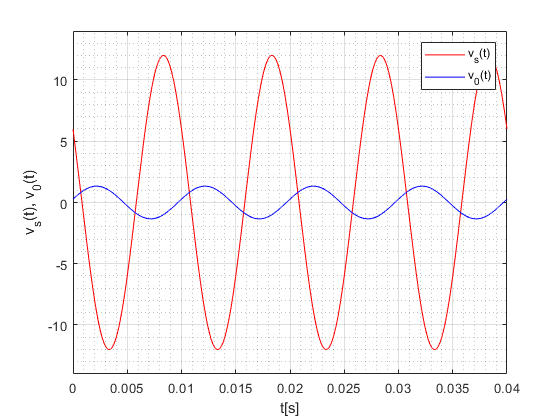

% ploting v0(t)
hold on
fplot(v0(t),[0.0 0.04],'b')
grid on; grid minor
xlabel('t[s]'); ylabel('v_s(t), v_0(t)')
axis([0 0.04 -Vm-2 Vm+2])
legend('v_s(t)', 'v_0(t)')

The current $I$  can be calculated using total impedance 

            
$$Z=R+Z_1$$


            
$$I=\frac{V}{Z}$$


Z = R+Z1

Z = 1.0000e+02 - 2.1315e+01i

I =V/Z

I = 0.0612 + 0.0131i

Finding current $i(t)$in time

%Cartesian to Polar
[theta_i, Im] = cart2pol(real(I),imag(I));

theta_i = 0.2100

Im = 0.0626

theta_id = theta_i*180/pi;
i(t) = Im*cos(w*t+theta_id);
digits(4)
i(t) = vpa(i(t))

$$i(t) = 0.06262\,\cos\left(628.3\,t+1.047\right)$$

 Ploting i(t)

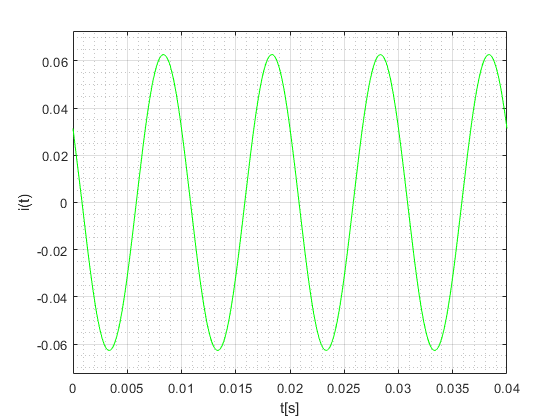

% ploting i(t)
figure()
fplot(i(t),[0.0 0.04],'g')
grid on; grid minor
xlabel('t[s]'); ylabel('i(t)')
axis([0 0.04 -Im-0.01 Im+0.01])

Circuit can be simulated  in MATLAB Simulink [./Simulink\Example_5.slx](matlab:open('./Simulink\Example_5.slx'))

    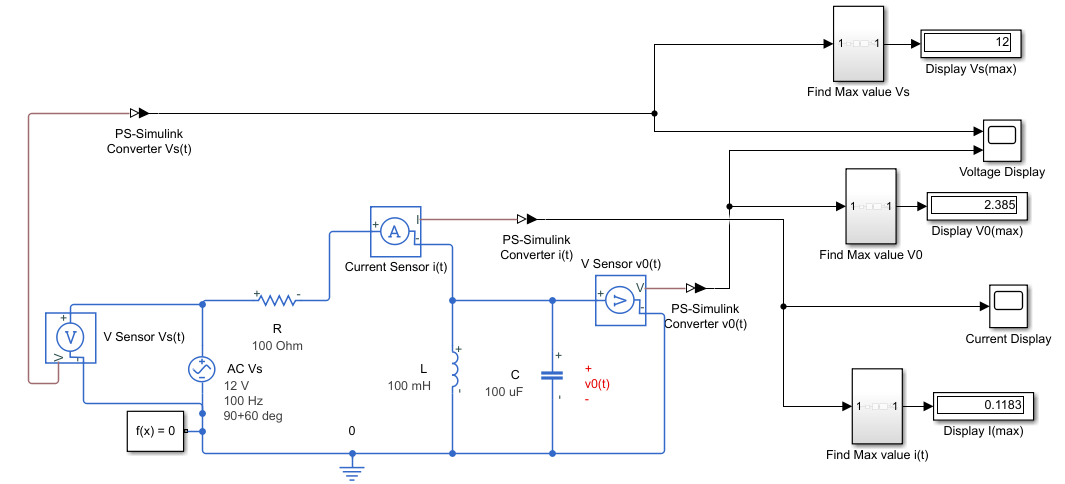

Voltages  $v_s(t)$and $v_0(t)$in the simulation is shown in the following figure

#### 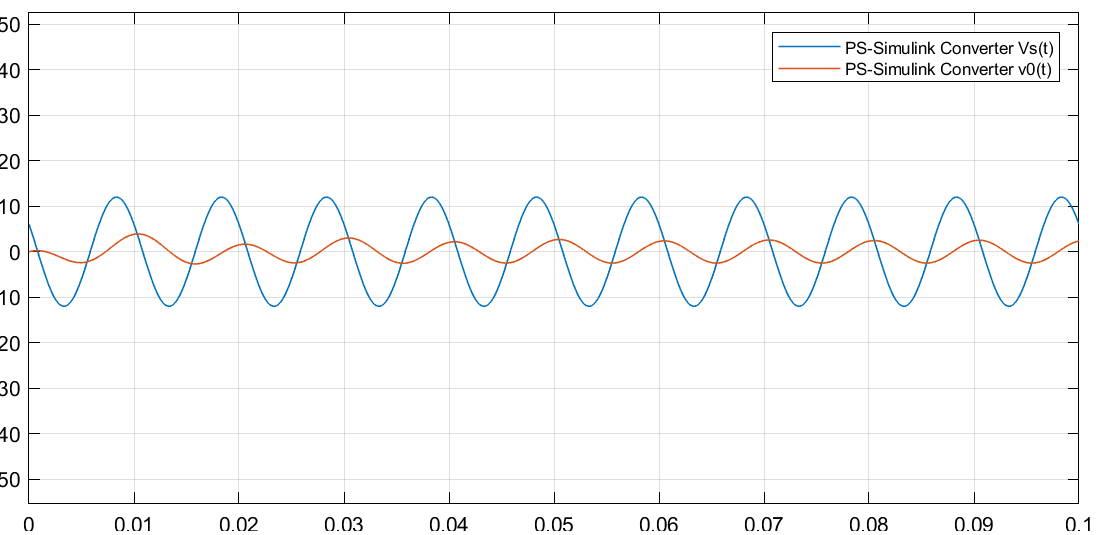

#### Exercise 5. Phasor-transformed circuit

Find the voltage $v_0(t)$ and current $i(t)$ in the circuit below for $v_s(t)=36cos(2\pi120t-30^\circ) $

                        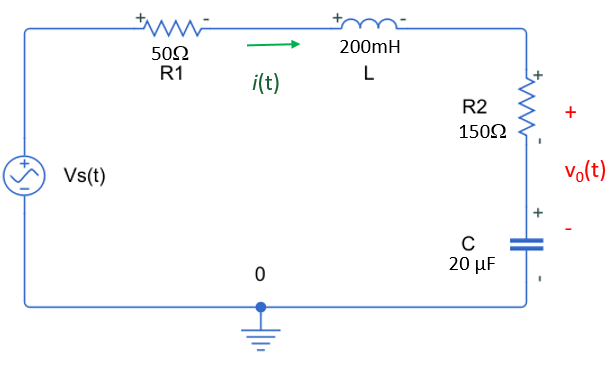

Given values in the circuit

% syms v(t) i(t)
% R1 = ;
% R2 = ;
% L = ;
% C =  ;
% Vm =         % Amplidute value
% w = ;        % frequency
% theta = ;    % phase in radians


Plotting input voltage source $v_s(t)$

% ploting v(t)
% vs(t)=Vm*cos(w*t+theta)
% figure ()
% fplot(vs(t),[0.0 0.04],'r')


Conver input source in cartesian form

% [Va, Vb] = pol2cart (theta, Vm);
% Vs = complex(Va, Vb)

Find the impedances

% XL = ?
% XC = ?

Find impedances Z1 as R1+XL and Z2 as R2+XC 

% Z1 = ?
% Z2 = ?

Using voltage division to find V0 

% V0 = ?

Find voltage $v_0(t)$ in time

% %Cartesian to Polar
% [theta_v, V0m]=cart2pol(real(V0),imag(V0))
% v0(t)=V0m*cos(w*t+theta_v);
% digits(4)
% v0(t)=vpa(v0(t))

Plot voltage $v_0(t)$a

% % ploting v0(t)
% hold on
% fplot(v0(t),[0.0 0.04],'b')
% grid on; grid minor
% xlabel('t[s]'); ylabel('v(t), i(t)')
% axis([0 0.04 -Vm-2 Vm+2])

Find current $I$  using the total impedance 

% Z = ?
% I = ?

Find voltage $i(t)$

% %Cartesian to Polar
% [theta_i, Im]=cart2pol(real(I),imag(I))
% 
% i(t)=Im*cos(w*t+theta_i);
% digits(4)
% i(t)=vpa(i(t))

 Plot i(t)

% % ploting i(t)
% figure()
% fplot(i(t),[0.0 0.04],'g')
% grid on; grid minor
% xlabel('t[s]'); ylabel('i(t)')
% axis([0 0.04 -Im-0.01 Im+0.01])

Simulate  this exercise using MATLAB Simulink to chek your values

        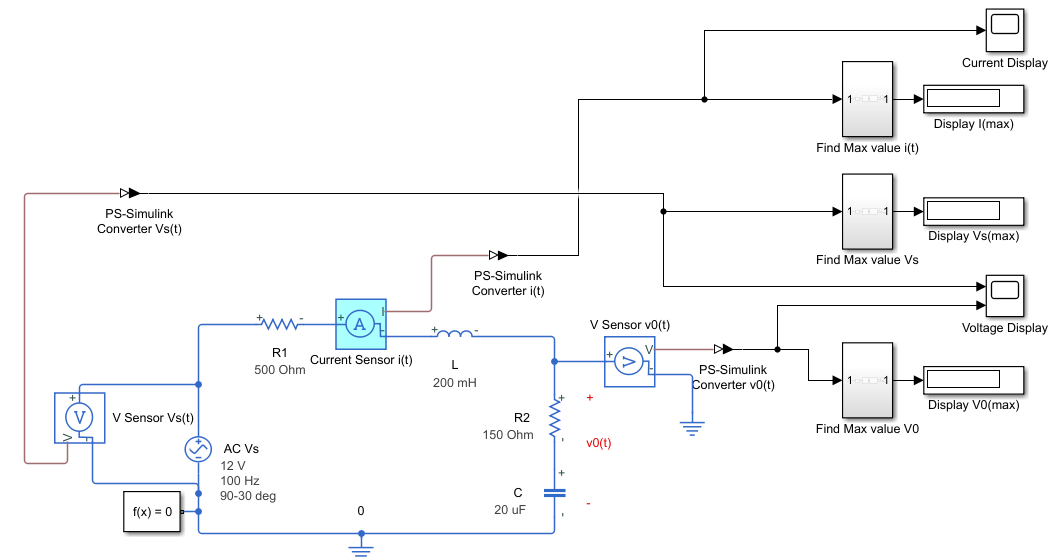

#### Example 6. Node Analysis in AC circuit

Find the voltage $v_0(t)$ and current $i(t)$ in the circuit below for $v_s(t)=36cos(2\pi100t) $

        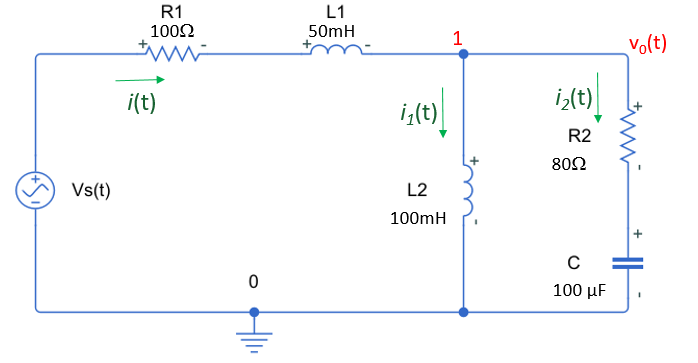       

Given values in the circuit

syms v(t) i(t)
R1 = 100; R2 =  80;
L1 = 50e-3; L2 = 100e-3;
C = 100e-6;
Vm = 36             % Amplidute value

Vm = 36

w = 2*pi*100;       % frequency
theta = 0*pi/180;  % phase in radians


Plotting input voltage source 

% ploting v(t)
vs(t)=Vm*cos(w*t+theta)

$$vs(t) = 36\,\cos\left(200\,\pi \,t\right)$$

figure ()
fplot(vs(t),[0.0 0.04],'r')

Conver input source in cartesian form

[Va, Vb] = pol2cart (theta, Vm);
Vs = complex(Va, Vb)

Vs = 36.0000 + 0.0000i

Find each impedance using 

        $X_L=j \omega L$  and $X_C=\frac{1}{j \omega C}$

XL1 = j*w*L1

XL1 = 0.0000 + 31.4159i

XL2 = j*w*L2

XL2 = 0.0000 + 62.8319i

XC = 1/(j*w*C)

XC = 0.0000 - 15.9155i

Applyying KCL at unknown nodes 1

          
$$I_1-I_2-I_3=0$$
      

Let's write each of the branch currents in terms of node voltages  using Ohm’s Law.

                        $I_1 = \frac{V_s -V_0 }{R_1+X_{L1}}$,      $I_2 = \frac{V_0}{X_{L2}}$,     $I_3 =  \frac{V_0 }{R_2+X_C}$,  

 Apply the branch currents equation to KCL equations at unknown nodes 1.

                          
$$\frac{V_s-V_0}{R_1+X_{L1}}-\frac{V_0}{X_{L2}}-\frac{V_0}{R_2+X_C}=0$$
     

 Unknown voltage V0 can be found using  MATLAB function `solve`                   

% Unknown node voltage V0
syms V0;

% Node equation and solution
V0 = solve ((Vs-V0)/(R1+XL1)-V0/XL2-V0/(R2+XC)==0);
digits(4)
V0 = vpa(V0)

$$V0 = 12.05+4.468\,\mathrm{i}$$

Finding voltage $v_0(t)$in time and ploting

% Cartesian to Polar
[theta_v, V0m] = cart2pol(real(V0),imag(V0))

$$theta\_v = 0.3552$$

$$V0m = 12.85$$

v0(t) = V0m*cos(w*t+theta_v);
digits(4)
% display in time domain
v0(t) = vpa(v0(t))

$$v0(t) = 12.85\,\cos\left(628.3\,t+0.3552\right)$$

Ploting $v_0(t)$

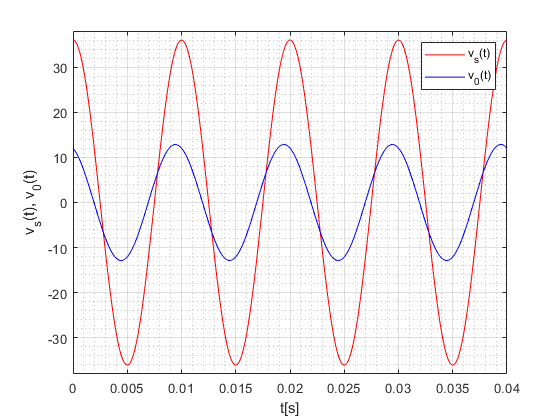

% ploting v0(t)
hold on
fplot(v0(t),[0.0 0.04],'b')
grid on; grid minor
xlabel('t[s]'); ylabel('v_s(t), v_0(t)')
axis([0 0.04 -Vm-2 Vm+2])
legend('v_s(t)', 'v_0(t)')

The current $I$  can be calculated using Vs and V0 

                
$$I=\frac{V_S-V_0}{R1+X_{L1}$$


% Find current I
I = (Vs-V0)/(R1+XL1)

$$I = \frac{23.95-4.468\,\mathrm{i}}{100+10\,\pi \,\mathrm{i}}$$

I=vpa(I)

$$I = 0.2053-0.1092\,\mathrm{i}$$

converting current $i(t)$in time

%Cartesian to Polar
[theta_i, Im] = cart2pol(real(I),imag(I))

$$theta\_i = -0.4888$$

$$Im = 0.2325$$


i(t) = Im*cos(w*t+theta_i);
% digits(4)
i(t) = vpa(i(t))

$$i(t) = 0.2325\,\cos\left(628.3\,t-0.4888\right)$$

 Ploting i(t)

% ploting i(t)
figure()
fplot(i(t),[0.0 0.04],'g')
grid on; grid minor
xlabel('t[s]'); ylabel('i(t)')
Im=double(Im)

Im = 0.2325

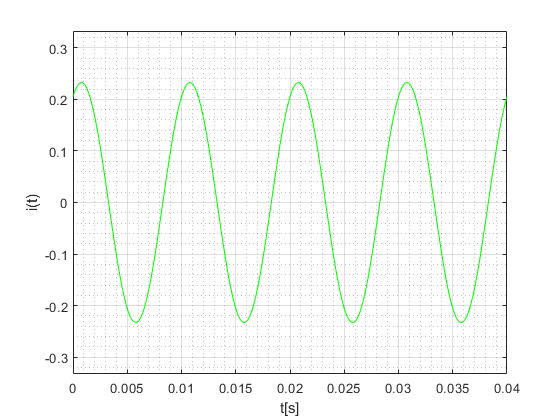

axis([0.0 0.04 -Im-0.1 Im+0.1])   

%axis([0.0 0.04 -0.3 0.3])

Circuit can be simulated  in MATLAB Simulink [./Simulink\Example_6.slx](matlab:open('./Simulink\Example_6.slx'))

### 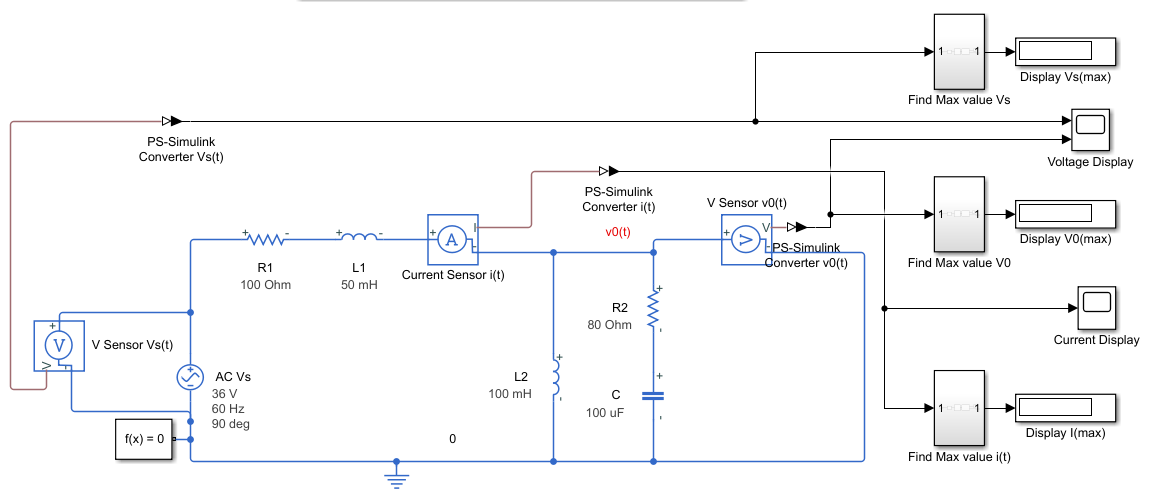

Waveform of $v_s(t)$ and $v_0(t)$ in MATLAB simulation is

            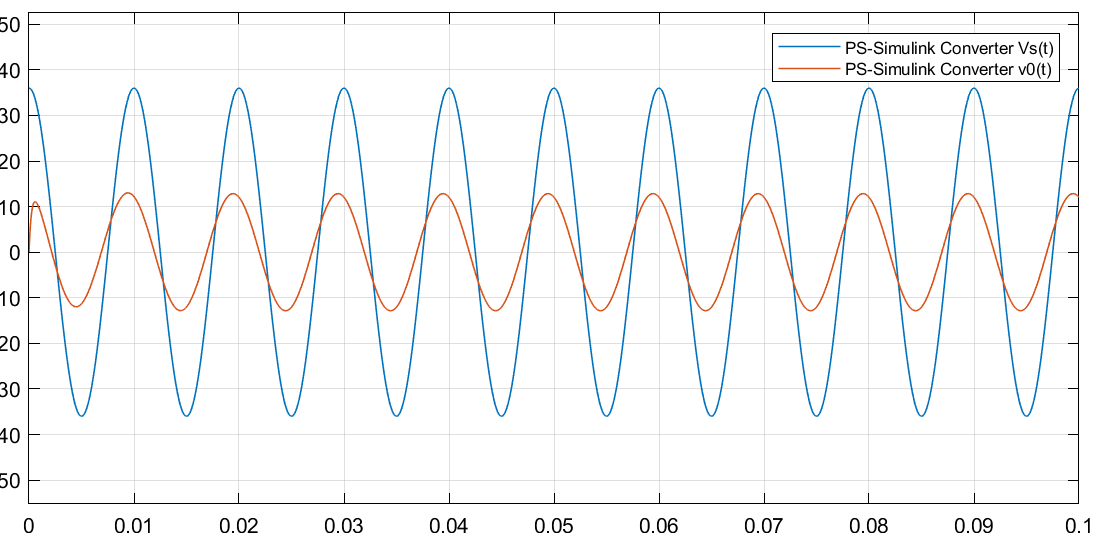

       Waveform of $i(t)$ in MATLAB simulation                                             

        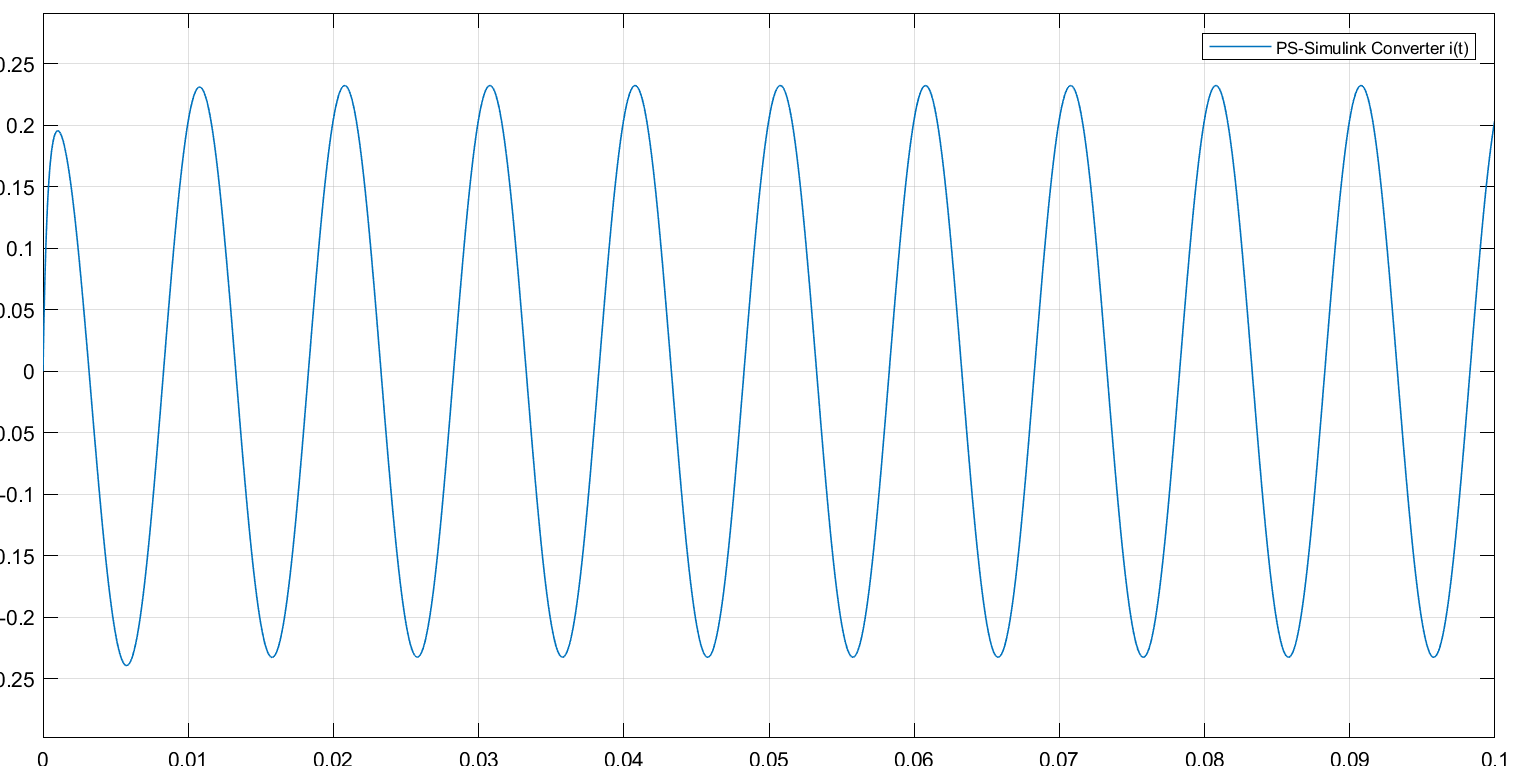

#### Exercise 6. Node Analysis in AC circuit

Find the voltage $v_0(t)$  in the circuit below for $v_{s1}(t)=36cos(2\pi60t) $and $v_{s1}(t)=12cos(2\pi60t) $

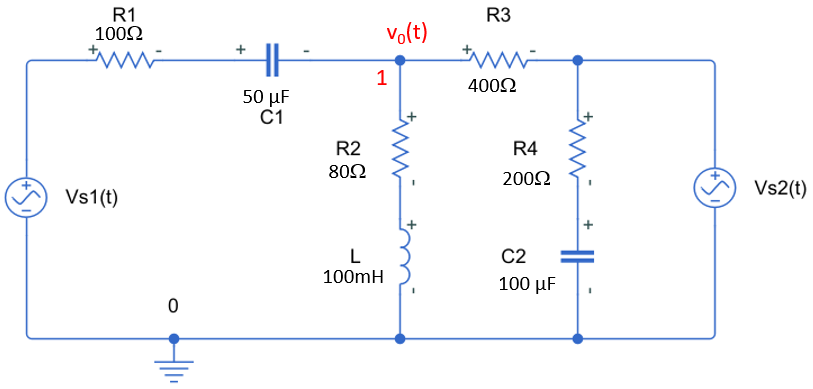

Given values in the circuit

% syms v(t)
% R1 = ?; R2 =  ?; R3 = ?; R4 =  ?;
% L = ? ; 
% C1 = ?; C2 = ?; 
% Vm1 = ?; theta1 = ?;           % Amplidute value and phase in radians
% Vm2 = ?; theta2 = ?;           % Amplidute value and phase in radians
% w = ?;       % frequency

Plotting input voltage sources 

% % ploting vs1(t) vs2(t)
% vs1(t) = ?
% vs1(t) = ?
% figure ()
% fplot(vs1(t),[0.0 0.04],'r')
% hold on
% fplot(vs2(t),[0.0 0.04],'b')

Conver input source in cartesian form

% [Va1, Vb1] = pol2cart (theta1, Vm1);
% Vs1 = complex(Va1, Vb1)
% [Va2, Vb2] = pol2cart (theta2, Vm2);
% Vs2 = complex(Va2, Vb2)

Find the impedances         

% XL = ?
% XC1 = ?
% XC2 = ?

Apply KCL at unknown nodes 1

Let's write each of the branch currents in terms of node voltages using Ohm’s Law .

 Apply the branch currents equation to KCL equations at unknown nodes 1.

 Use MATLAB `solve` function to find unknown voltage V0 as follow.                   

% % Unknown node voltage V0
% syms V0;
% 
% % Node equation and solution
% V0 = solve (??);
% digits(4)
% V0=vpa(V0)

Finding voltage $v_0(t)$in time and ploting

% % Cartesian to Polar
% [theta_v, V0m] = cart2pol(real(V0),imag(V0))
% v0(t) = V0m*cos(w*t+theta_v);
% digits(4)
% % display in time domain
% v0(t) = vpa(v0(t))

Ploting v0(t)


% % ploting v0(t)
% hold on
% fplot(v0(t),[0.0 0.04],'c')
% grid on; grid minor
% xlabel('t[s]'); ylabel('v_s(t), v_0(t)')
% axis([? ? ? ?])
% legend('v_{s1}(t)', 'v_{s2}(t)', 'v_0(t)')

Simulate  this exercise using MATLAB Simulink to chek your values. 

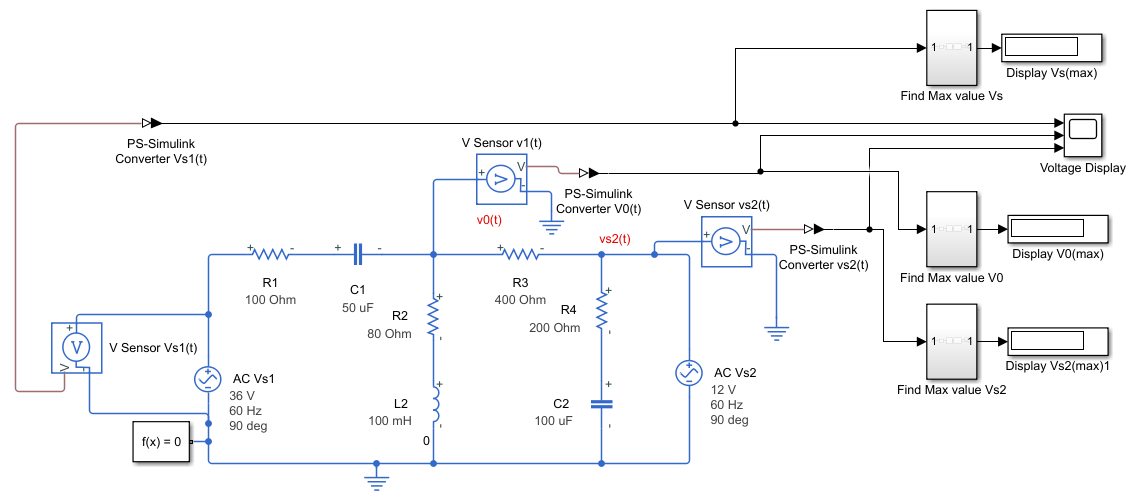

#### Example 7. Mesh Analysis in AC circuit

Find the current $i_2(t)$and $i_3(t)$and voltage $v_0(t)$ in the circuit below for $i_s(t)=0.2cos(2\pi60t) $and $v_s(t)=36cos(2\pi60t-45^\circ) $

        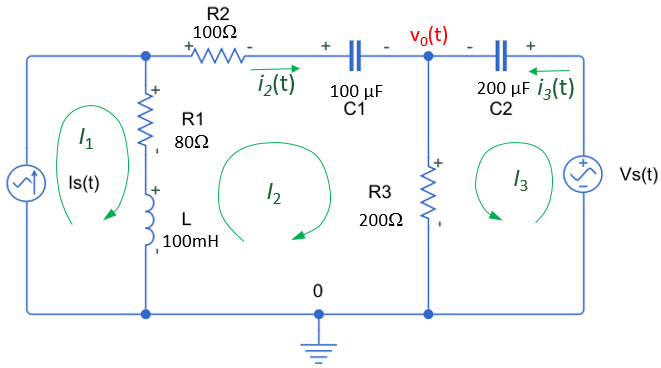       

Given values in the circuit

syms v(t) i(t)
R1 = 80; R2 =  100; R3 =  200;
L = 100e-3; 
C1 = 100e-6; C2 = 200e-6;
Im = 0.2;  theta_i = 0*pi/180; %current source amp and phase in radians
Vm = 36 ; theta_v = -45*pi/180;  %Voltage source amp and phase in radians         
w = 2*pi*60;       % frequency

% Plotting input voltage source 

% % ploting v(t)
% vs(t)=Vm*cos(w*t+theta)
% figure ()
% fplot(vs(t),[0.0 0.04],'r')

Conver input sources in cartesian form

[Ia, Ib] = pol2cart (theta_i, Im);
Is = complex(Ia, Ib)

Is = 0.2000 + 0.0000i


[Va, Vb] = pol2cart (theta_v, Vm);
Vs = complex(Va, Vb)

Vs = 25.4558 - 25.4558i

Finding the impedances 

        $X_L=j \omega L$  and $X_C=\frac{1}{j \omega C}$

XL = j*w*L

XL = 0.0000 + 37.6991i

XC1 = 1/(j*w*C1)

XC1 = 0.0000 - 26.5258i

XC2 = 1/(j*w*C2)

XC2 = 0.0000 - 13.2629i

The mesh current in loop 1 is defined as $I_1=I_S$

Apply KVL to each unknown mesh current $I_2$and $I_3$

                               Loop 2 :  $(R_2+X_{C1})I_2+R_3(I_2 +I_3)+(R_1+X_L)(I_2-I_1)=0$

                               Loop 3 :   $X_{C2}I_3+R_3(I_3 + I_2)-V_{S1}=0$

Use MATLAB `solve`  to find unknown current I1, I2, and I3 as follow.

% Unknown mesh current I1, I2, I3
syms I1 I2 I3;

% Mesh equations and solutions
[I1,I2, I3] = solve (I1==Is, (R2+XC1)*I2 + R3*(I2+I3)+(R1+XL)*(I2-I1)==0, XC2*I3+R3*(I3+I2)-Vs==0);
digits(4)
I1=vpa(I1)

$$I1 = 0.2$$

I2=vpa(I2)

$$I2 = -0.06288+0.1718\,\mathrm{i}$$

I3=vpa(I3)

$$I3 = 0.2091-0.2852\,\mathrm{i}$$

Finding currents $i_2(t)$and $i_3(t)$ in time and ploting

% Cartesian to Polar for I2
[theta_i2, I2m] = cart2pol(real(I2),imag(I2));
i2(t) = I2m*cos(w*t+theta_i2);
digits(4)
% display in time domain
i2(t) = vpa(i2(t))

$$i2(t) = 0.183\,\cos\left(377.0\,t+1.922\right)$$


% Cartesian to Polar for I3
[theta_i3, I3m] = cart2pol(real(I3),imag(I3));
i3(t) = I3m*cos(w*t+theta_i3);
digits(4)
% display in time domain
i3(t) = vpa(i3(t))

$$i3(t) = 0.3536\,\cos\left(377.0\,t-0.9382\right)$$

Ploting currents $i_2(t)$and $i_3(t)$

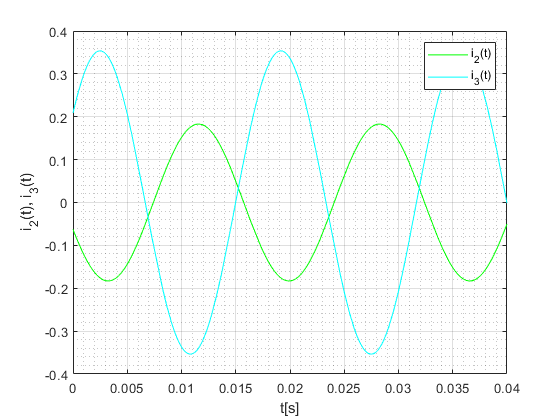

% ploting i2(t) and i3(t)
figure ()
fplot(i2(t),[0.0 0.04],'g')
hold on
fplot(i3(t),[0.0 0.04],'c')
grid on; grid minor
xlabel('t[s]'); ylabel('i_2(t), i_3(t)')
axis([0 0.04 -2*Im 2*Im])
legend('i_2(t)', 'i_3(t)')

The voltage V0  can be calculated using I2 and I3

                
$$V_0 = (I_2-I_3)*R_3$$


% Find voltage cross resistor R3 
V0 = (I2+I3)*R3

$$V0 = 29.24-22.68\,\mathrm{i}$$

V0 = vpa(V0)

$$V0 = 29.24-22.68\,\mathrm{i}$$

Finding voltage $v_0(t)$in time

%Cartesian to Polar
[theta_v0, V0m] = cart2pol(real(V0),imag(V0))

$$theta\_v0 = -0.6598$$

$$V0m = 37.01$$


v0(t) = V0m*cos(w*t+theta_v0);
% digits(4)
v0(t) = vpa(v0(t))

$$v0(t) = 37.01\,\cos\left(377.0\,t-0.6598\right)$$

 Ploting $v_0(t)$

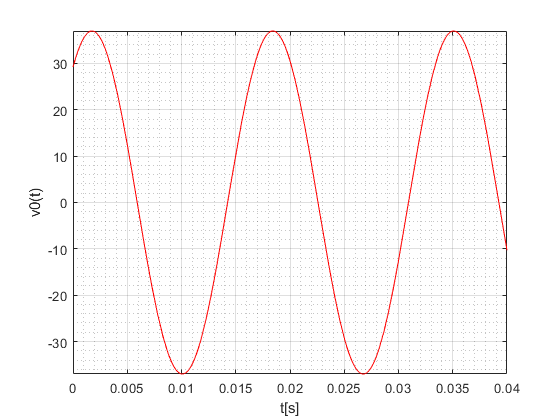

% ploting v0(t)   
figure()
fplot(v0(t),[0.0 0.04],'r')
grid on; grid minor
xlabel('t[s]'); ylabel('v0(t)')

% axis([0.0 0.04 -0.3 0.3])

Circuit can be simulated  in MATLAB Simulink  [./Simulink\Example_7.slx](matlab:open('./Simulink\Example_7.slx'))

### 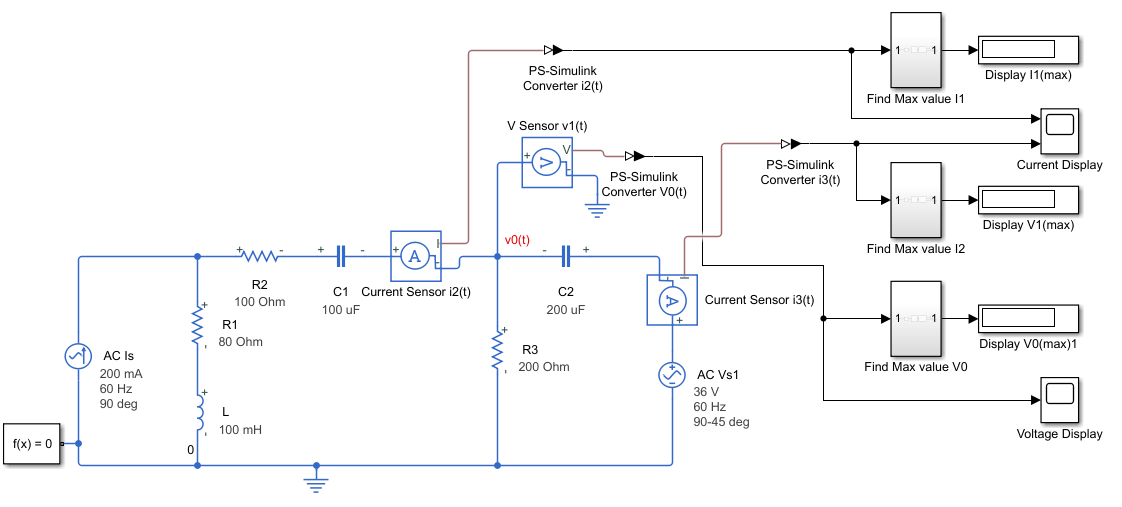

Waveform of $i_2(t)$ and $i_3(t)$ in MATLAB simulation

            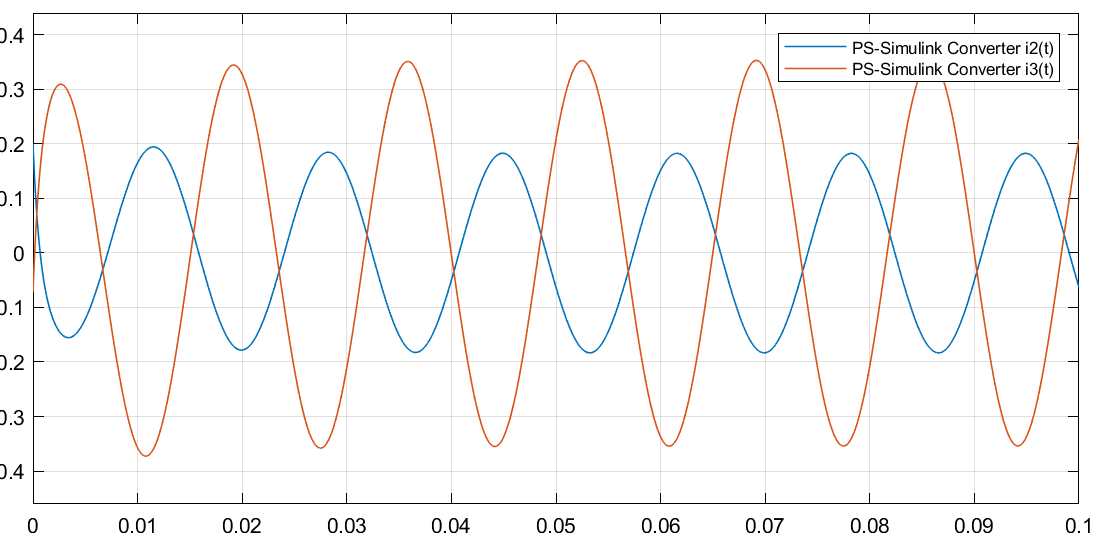

       Waveform of $v_0(t)$ in MATLAB simulation                                             

            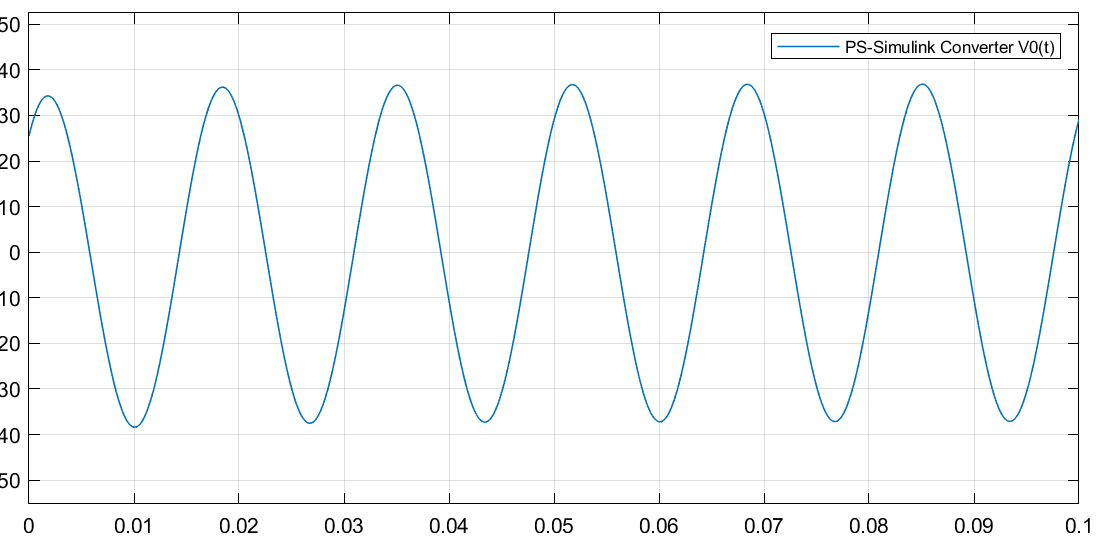

#### Exercise 7. Mesh Analysis in AC circuit

Find the current $i_2(t)$, $i_3(t)$and voltage $v_1(t)$ $v_2(t)$ in the circuit below for $i_s(t)=0.5cos(2\pi100t) $and $v_s(t)=12cos(2\pi100t-45^\circ) $

        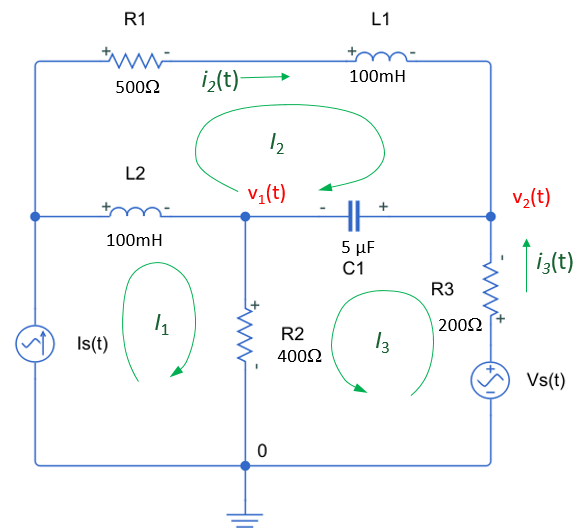       

**Solution steps**

Given values in the circuit

% syms vs(t) is(t)
% R1 = ? ; R2 = ?; R3 = ?;
% L1 = ? ; L2 = ? ;
% C1 = 1?; 
% Im = ?;  theta_i = ?; %current source amp and phase in radians
% Vm = ? ; theta_v = ?;  %Voltage source amp and phase in radians         
% w = ?;       % frequency

Conver input sources in cartesian form

% [Ia, Ib] = pol2cart (theta_i, Im);
% Is = complex(Ia, Ib)
% 
% [Va, Vb] = pol2cart (theta_v, Vm);
% Vs = complex(Va, Vb)

Find the impedances 

% XL1 = ?
% XL2 = ?
% XC1 = ?

Find a mesh current which is  defined 

Apply KVL to each unknown mesh currents

Use MATLAB solve the equations to find unknown current I1, I2, and I3 as follow.

% % Mesh current I1, I2, I3
% syms I1 I2 I3;
% 
% % Mesh equations and solutions
% [I1,I2, I3] = solve (?, ?, ?);
% digits(4)
% I1=vpa(I1)
% I2=vpa(I2)
% I3=vpa(I3)

Find currents $i_2(t)$and $i_3(t)$ in time

% % Cartesian to Polar
% [theta_i2, I2m] = cart2pol(real(I2),imag(I2));
% i2(t) = I2m*cos(w*t+theta_i2);
% digits(4)
% % display in time domain
% i2(t) = vpa(i2(t))
% 
% [theta_i3, I3m] = cart2pol(real(I3),imag(I3));
% i3(t) = I3m*cos(w*t+theta_i3);
% digits(4)
% % display in time domain
% i3(t) = vpa(i3(t))


Plot currents $i_2(t)$and $i_3(t)$

% % ploting i2(t) and i3(t)
% figure ()
% fplot(i2(t),[0.0 0.04],'g')
% hold on
% fplot(i3(t),[0.0 0.04],'c')
% grid on; grid minor
% xlabel('t[s]'); ylabel('i_2(t), i_3(t)')
% axis([0 0.04 -2*Im 2*Im])
% legend('i_2(t)', 'i_3(t)')

Find voltage V1 and V2  using I2 an I3       

% % Find voltages V1 and V2 
% V1 = ? ;
% V1=vpa(V1)
% V2 = ? ;
% V2=vpa(V2)

Find voltage $v_1(t)$and $v_2(t)$in time

% %Cartesian to Polar
% [theta_v1, V1m] = cart2pol(real(V1),imag(V1))
% v1(t) = V1m*cos(w*t+theta_v1);
% % digits(4)
% v1(t) = vpa(v1(t))
% 
% [theta_v2, V2m] = cart2pol(real(V2),imag(V2))
% v2(t) = V2m*cos(w*t+theta_v2);
% % digits(4)
% v2(t) = vpa(v2(t))


 Plot $v_1(t)$and $v_2(t)$i

% % ploting v1(t) and v2(t)
% figure()
% fplot(v1(t),[0.0 0.04],'r')
% hold on;
% fplot(v2(t),[0.0 0.04],'b')
% grid on; grid minor
% xlabel('t[s]'); ylabel('v0(t)')
% legend('v_1(t)', 'v_2(t)')


Simulate  this exercise using MATLAB Simulink to chek your values.

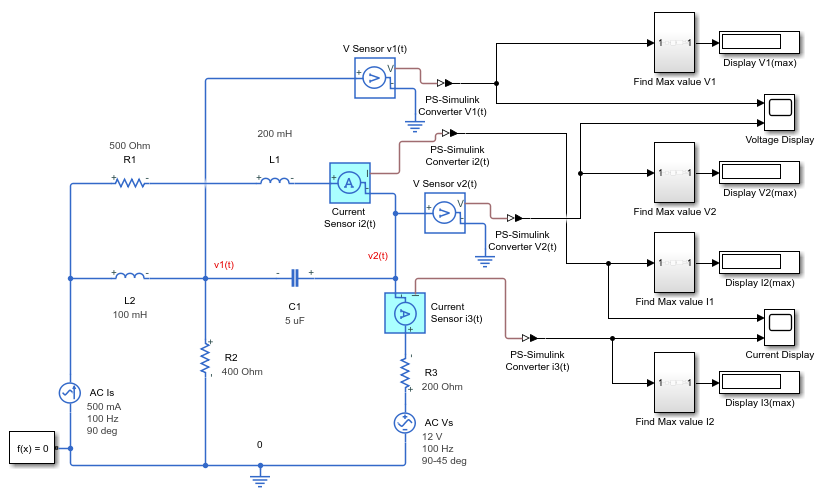  

### References/Additional Info

***Electric Circuits***, James Kang, 1st ed. Cengage Learning, 2018